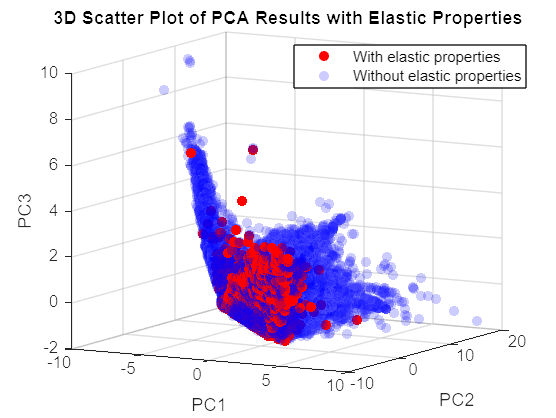

% Load the data from the CSV file
pcaData = readtable('pca_df.csv');

% Extract the first three principal components
PC1 = pcaData.PC1;
PC2 = pcaData.PC2;
PC3 = pcaData.PC3;
has_elastic_props = pcaData.has_elastic_props;

% Create a 3D scatter plot with colors based on 'has_elastic_props'
figure;
hold on;
scatter3(PC1(has_elastic_props==1), PC2(has_elastic_props==1), PC3(has_elastic_props==1), 'filled', 'r');
scatter3(PC1(has_elastic_props==0), PC2(has_elastic_props==0), PC3(has_elastic_props==0), 'filled', 'b', 'MarkerFaceAlpha', 0.2);
xlabel('PC1');
ylabel('PC2');
zlabel('PC3');
title('3D Scatter Plot of PCA Results with Elastic Properties');

% Add legend
legend('With elastic properties', 'Without elastic properties');

% Improve the visualization with grid and rotate for better view
grid on;
view(-30, 10); % Adjust viewing angle for better perspective
hold off;

xlim([-10.0 10.0])
ylim([-10.0 20.0])
zlim([-2.00 10.00])
view([41.94 -14.15])